**P.34**

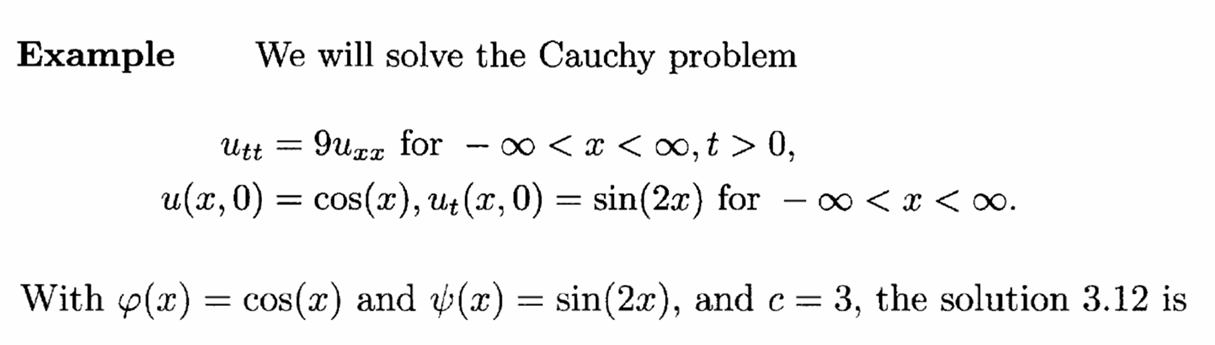

clearvars;
clc;
syms x t u(x,t) phi(x) psi(x)
c = 3;
WaveEq = c^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = 9\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

t0 = u(x,0) == cos(x)

$$t0 = u\left(x,0\right)=\cos\left(x\right)$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == sin(2*x)

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=\sin\left(2\,x\right)$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = \frac{\cos\left(3\,t+x\right)}{2}+\frac{\cos\left(3\,t-x\right)}{2}$$

u2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$u2 = \frac{{\sin\left(3\,t+x\right)}^{2}}{6}-\frac{{\sin\left(3\,t-x\right)}^{2}}{6}$$

u(x,t) = simplify(u1+u2)

$$u(x, t) = \frac{\cos\left(3\,t\right)\,\cos\left(x\right)\,\left(2\,\sin\left(3\,t\right)\,\sin\left(x\right)+3\right)}{3}$$

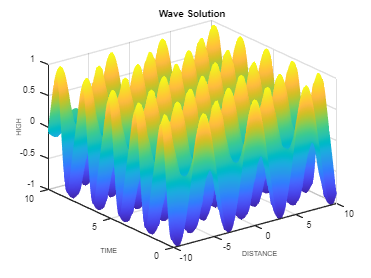

clf; figure
fsurf(u,[-10 10 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**Wave profile at different times**

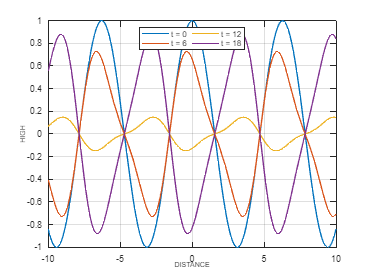

clf 
tm = [0 6 12 18];
for i = 1:length(tm)
    sn = matlabFunction(u(x,tm(i)));
    fplot(sn, [-10 10])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8)
ylabel('HIGH','FontSize',8)
legend('t = 0','t = 6','t = 12','t = 18','Location','north','NumColumns',2)

**Wave profile at various distance**

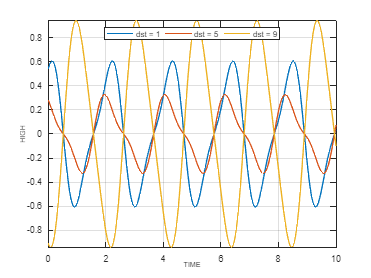

clf 
dst = [1 5 9];
for i = 1:length(dst)
    sn = matlabFunction(u(dst(i),t));
    fplot(sn, [0 10])
    grid on, hold on
end
xlabel('TIME','FontSize',8)
ylabel('HIGH','FontSize',8)
legend('dst = 1','dst = 5','dst = 9','Location','north','NumColumns',3)

**P.36**

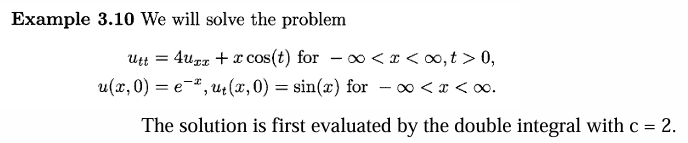

clearvars
clc
syms x t u(x,t) phi(x) psi(x) tau xx
c = 2;
f(x,t) = x*cos(t);
WaveEq = c^2*diff(u,x,2)+f(x,t) == diff(u,t,2)

$$WaveEq(x, t) = 4\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)+x\,\cos\left(t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

t0 = u(x,0) == exp(-x)

$$t0 = u\left(x,0\right)={\mathrm{e}}^{-x}$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == sin(x)

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=\sin\left(x\right)$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = \frac{{\mathrm{e}}^{-2\,t-x}}{2}+\frac{{\mathrm{e}}^{2\,t-x}}{2}$$

u2 = (subs(int(psi),x,x+c*t)-subs(int(psi),x,x-c*t))/(2*c)

$$u2(x) = \frac{\cos\left(2\,t-x\right)}{4}-\frac{\cos\left(2\,t+x\right)}{4}$$

u3 = int(int(f(x,t),x,[x-c*(tau-t) x+c*(tau-t)]),t,[0 tau])/(2*c)

$$u3 = -2\,x\,\left(\frac{\cos\left(\tau \right)}{2}-\frac{1}{2}\right)$$

u = simplify(u1+u2+subs(u3,'tau',t))

$$u(x) = x+\frac{{\mathrm{e}}^{-2\,t-x}}{2}+\frac{{\mathrm{e}}^{2\,t-x}}{2}+\frac{\sin\left(2\,t\right)\,\sin\left(x\right)}{2}-x\,\cos\left(t\right)$$

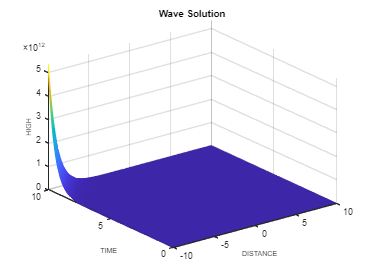

clf; figure
fsurf(u,[-10 10 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**P.38**

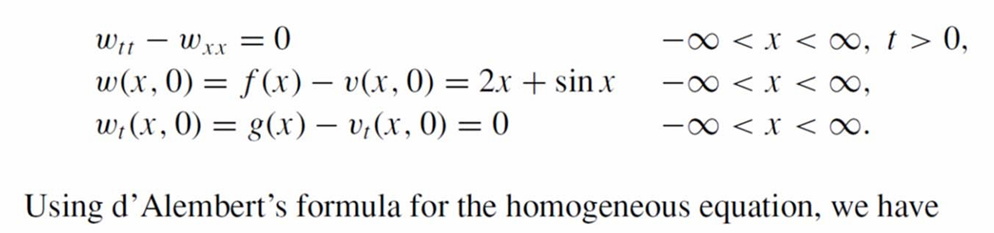

**Force response v(t)**

clear
clc
syms t v(t)
steadyS = diff(v,t,2)-t^7 == 0

$$steadyS(t) = \frac{\partial^{2}}{\partial t^{2}}v\left(t\right)-t^{7}=0$$

t0 = v(0) ==0

$$t0 = v\left(0\right)=0$$

Dt = diff(v,t)

$$Dt(t) = \frac{\partial }{\partial t}v\left(t\right)$$

Dt0 = Dt(0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}v\left(t\right)\right)|}_{t=0}\right)=0$$

v(t) = dsolve(steadyS,[t0 Dt0])

$$v(t) = \frac{t^{9}}{72}$$

**Transient w(x,t) = u(x,t)-v(x)**

syms x t w(x,t) phi(x) psi(x)
c = 1;
WaveEq = c^2*diff(w,x,2) == diff(w,t,2)

$$WaveEq(x, t) = \frac{\partial^{2}}{\partial x^{2}}w\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}w\left(x,t\right)$$

t0 = w(x,0) == 2*x+sin(x)

$$t0 = w\left(x,0\right)=2\,x+\sin\left(x\right)$$

Dt = diff(w,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}w\left(x,t\right)\right)|}_{t=0}\right)=0$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);
w1 = (phi(x-c*t)+phi(x+t*c))/2

$$w1 = 2\,x-\frac{\sin\left(t-x\right)}{2}+\frac{\sin\left(t+x\right)}{2}$$

w2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$w2 = 0$$

w = simplify(w1+w2)

$$w = 2\,x+\cos\left(t\right)\,\sin\left(x\right)$$

u = w+v

$$u(t) = 2\,x+\cos\left(t\right)\,\sin\left(x\right)+\frac{t^{9}}{72}$$

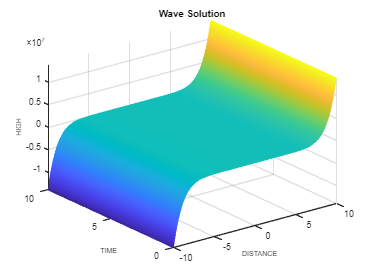

clf; figure
fsurf(u,[-10 10 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**Using nonhomogeneous d'Alembert**

syms x t u(x,t) phi(x) psi(x) tau 
c = 1;
f(x,t) = t^7;
WaveEq = c^2*diff(u,x,2)+f(x,t) == diff(u,t,2)

$$WaveEq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)+t^{7}=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

t0 = u(x,0) == 0

$$t0 = u\left(x,0\right)=0$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=0$$

phi(x) = rhs(t0); psi(x) = rhs(Dt0);
u1 = (phi(x-c*t)+phi(x+c*t))/2

$$u1 = 0$$

u2 = int(psi,x,[x-c*t x+c*t])/(2*c)

$$u2 = 0$$

u3 = int(f(x,t),x,[x-c*(tau-t) x+c*(tau-t)])

$$u3 = -2\,t^{7}\,\left(t-\tau \right)$$

u31 = int(u3,t,[0 tau])/(2*c)

$$u31 = \frac{\tau^{9}}{72}$$

u32 = int(int(f(x,t),x,[x-c*(tau-t) x+c*(tau-t)]),t,[0 tau])/(2*c)

$$u32 = \frac{\tau^{9}}{72}$$

u = simplify(u1+u2+subs(u31,'tau',t))

$$u = \frac{t^{9}}{72}$$

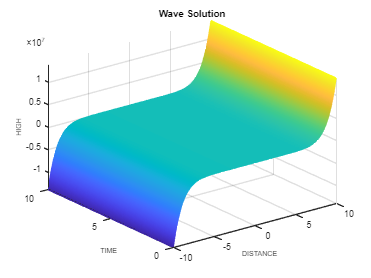

clf; figure
fsurf(u,[-10 10 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**Laplace transform ODE**

**P.45**

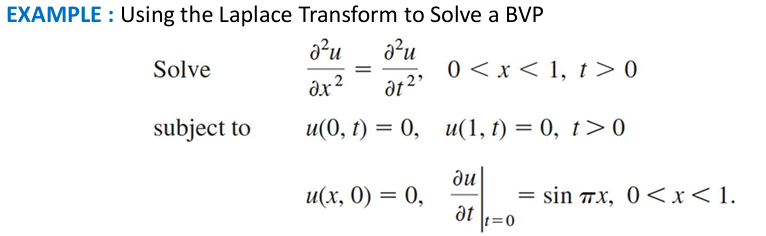

clc; clearvars;
syms x t s u(x,t) U(x,s) Y(x)
Dt = diff(u,t)

$$Dt(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)$$

D2t = diff(Dt,t)

$$D2t(x, t) = \frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

D2x = diff(u,x,2)

$$D2x(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

eqn = laplace(D2t == D2x,t,s)

$$eqn(x) = s^{2}\,\mathrm{laplace}\left(u\left(x,t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)-s\,u\left(x,0\right)=\mathrm{laplace}\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right),t,s\right)$$

cond1 = u(0,t) == 0

$$cond1 = u\left(0,t\right)=0$$

cond2 = u(1,t) == 0

$$cond2 = u\left(1,t\right)=0$$

eqn = subs(eqn,{laplace(u,t,s),u(x,0),Dt(x,0),laplace(D2x,t,s)},{U(x,s),0,sin(pi*x),subs(D2x,{u,t},{U,s})})

$$eqn(x) = s^{2}\,U\left(x,s\right)-\sin\left(\pi \,x\right)=\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond1 = laplace(cond1,t,s)

$$cond1 = \mathrm{laplace}\left(u\left(0,t\right),t,s\right)=0$$

cond2 = laplace(cond2,t,s)

$$cond2 = \mathrm{laplace}\left(u\left(1,t\right),t,s\right)=0$$

cond1 = subs(cond1,laplace(u(0,t),t,s),U(0,s))

$$cond1 = U\left(0,s\right)=0$$

cond2 = subs(cond2,laplace(u(1,t),t,s),U(1,s))

$$cond2 = U\left(1,s\right)=0$$

eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s^{2}\,Y\left(x\right)-\sin\left(\pi \,x\right)=\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond_1 = subs(cond1,U,Y)

$$cond\_1 = Y\left(0\right)=0$$

cond_2 = subs(cond2,U,Y)

$$cond\_2 = Y\left(1\right)=0$$

sol_g =dsolve(eqn_n)

$$sol\_g = C_{1}\,{\mathrm{e}}^{s\,x}+C_{2}\,{\mathrm{e}}^{-s\,x}+\frac{\pi \,\cos\left(\pi \,x\right)+s\,\sin\left(\pi \,x\right)}{2\,s\,\left(s^{2}+\pi^{2}\right)}-\frac{\pi \,\cos\left(\pi \,x\right)-s\,\sin\left(\pi \,x\right)}{2\,s\,\left(s^{2}+\pi^{2}\right)}$$

sol = dsolve(eqn_n,[cond_1 cond_2])

$$sol = \frac{\sin\left(\pi \,x\right)}{s^{2}+\pi^{2}}$$

sol_t(x,t) = ilaplace(sol,s,t)

$$sol\_t(x, t) = \frac{\sin\left(\pi \,t\right)\,\sin\left(\pi \,x\right)}{\pi }$$

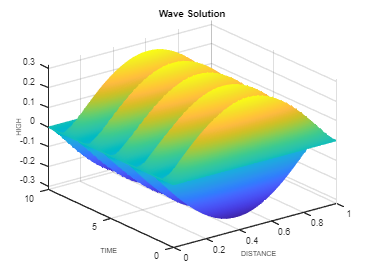

clf; figure
fsurf(sol_t,[0 1 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('DISTANCE','FontSize',8)
ylabel('TIME','FontSize',8)
zlabel('HIGH','FontSize',8)

**P**.**53**

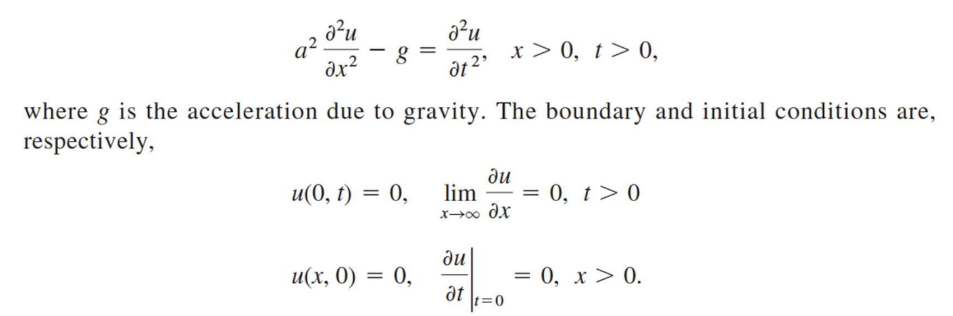

clc; clf; clearvars;
syms x t s u(x,t) U(x,s) Y(x) a g UnitSp(x)
Dt = diff(u,t); D2t = diff(Dt,t);
Dx = diff(u,x); D2x = diff(Dx,x);
eqn = laplace(D2t == a^2*D2x-g,t,s)

$$eqn(x) = s^{2}\,\mathrm{laplace}\left(u\left(x,t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)-s\,u\left(x,0\right)=a^{2}\,\mathrm{laplace}\left(\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right),t,s\right)-\frac{g}{s}$$

cond1 = u(0,t) == 0; cond2 = Dx(inf,t) == 0;
eqn = subs(eqn,{laplace(u,t,s),u(x,0),Dt(x,0),laplace(D2x,t,s)},{U(x,s),0,0,subs(D2x,{u,t},{U,s})})

$$eqn(x) = s^{2}\,U\left(x,s\right)=a^{2}\,\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)-\frac{g}{s}$$

cond1 = laplace(cond1,t,s); cond2 = laplace(cond2,t,s);
cond1 = subs(cond1,laplace(u(0,t),t,s),U(0,s))

$$cond1 = U\left(0,s\right)=0$$

cond2 = subs(cond2,laplace(Dx(inf,t),t,s),U(inf,s))

$$cond2 = U\left(\infty ,s\right)=0$$

eqn_n = subs(eqn,U,Y);
cond_1 = subs(cond1,U,Y); cond_2 = subs(cond2,U,Y);
sol_g = dsolve(eqn_n)

$$sol\_g = C_{1}\,{\mathrm{e}}^{\frac{s\,x}{a}}+C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{g}{s^{3}}$$

Dsol = diff(sol_g,x);
sol = subs(sol_g,sym('C1'),0)

$$sol = C_{2}\,{\mathrm{e}}^{-\frac{s\,x}{a}}-\frac{g}{s^{3}}$$

C2 = solve(subs(sol,x,0)==0,sym('C2'))

$$C2 = \frac{g}{s^{3}}$$

sol = subs(sol,sym('C2'),C2)

$$sol = \frac{g\,{\mathrm{e}}^{-\frac{s\,x}{a}}}{s^{3}}-\frac{g}{s^{3}}$$

sol_t = ilaplace(sol,s,t);
sol_t = subs(sol_t,ilaplace(exp(-s*x/a)/s^3,s,t),(t-x/a)^2*(UnitSp(t-x/a))/2)

$$sol\_t = \frac{g\,\mathrm{UnitSp}\left(t-\frac{x}{a}\right)\,{\left(t-\frac{x}{a}\right)}^{2}}{2}-\frac{g\,t^{2}}{2}$$

**Plot soluton**

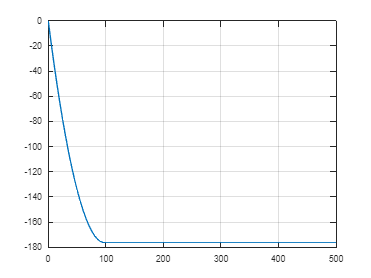

clf
syms x;
g = 1.8;
a =7;
t =14;
y = piecewise((0 <= x) & (x < a*t),-g*(2*a*x*t-x^2)/(2*a^2),x >= a*t, -(g*t^2)/2);
i = linspace(0,500);
plot(i,subs(y,x,i))
xlim([0 500])
grid on

**P.53**

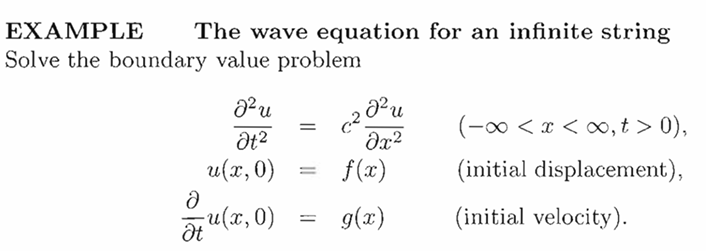

### **Using the Fourier Transform**

clear
clc
clearvars
syms x t w c u(x,t) U(w,t) Y(t) f(x) g(x) F(w) G(w) cf
Dt = diff(u,t)

$$Dt(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)$$

D2t = diff(Dt,t)

$$D2t(x, t) = \frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

D2x = diff(u,x,2)

$$D2x(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

eqn = fourier(D2t == c^2*D2x,x,w)

$$eqn(t) = \mathrm{fourier}\left(\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right),x,w\right)=-c^{2}\,w^{2}\,\mathrm{fourier}\left(u\left(x,t\right),x,w\right)$$

eqn = subs(eqn,{fourier(D2t,x,w),fourier(u,x,w)},{subs(D2t,{u,x},{U,w}),U})

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}U\left(w,t\right)=-c^{2}\,w^{2}\,U\left(w,t\right)$$

eqn = subs(eqn,U(w,t),Y(t))

$$eqn(t) = \frac{\partial^{2}}{\partial t^{2}}Y\left(t\right)=-c^{2}\,w^{2}\,Y\left(t\right)$$

cond1 = Y(0) == F(w)

$$cond1 = Y\left(0\right)=F\left(w\right)$$

cond2 = subs(diff(Y(t)),t,0) == G(w)

$$cond2 = \left({\left(\frac{\partial }{\partial t}Y\left(t\right)\right)|}_{t=0}\right)=G\left(w\right)$$

sol = collect(dsolve(eqn,[cond1 cond2]),[F G])

$$sol = \left(\frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}}{2}\right)\,F\left(w\right)+\left(\frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}-\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}\right)\,G\left(w\right)$$

var = children(sol);
cof1 = coeffs(cell2sym(var(1)),str2sym('F(w)'))

$$cof1 = \frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}}{2}+\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}}{2}$$

cof2 = coeffs(cell2sym(var(2)),str2sym('G(w)'))

$$cof2 = \frac{{\mathrm{e}}^{-c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}-\frac{{\mathrm{e}}^{c\,t\,w\,\mathrm{i}}\,\mathrm{i}}{2\,c\,w}$$

sol = subs(sol,{cof1,cof2},{cos(c*w*t),sin(c*w*t)/(c*w)})

$$sol = \cos\left(c\,t\,w\right)\,F\left(w\right)+\frac{\sin\left(c\,t\,w\right)\,G\left(w\right)}{c\,w}$$

u(x,t) = subs(cf*int(sol*exp(1i*w*x),w,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$u(x, t) = \frac{\sqrt{2}\,\int_{-\infty }^{\infty }{\mathrm{e}}^{w\,x\,\mathrm{i}}\,\left(\cos\left(c\,t\,w\right)\,F\left(w\right)+\frac{\sin\left(c\,t\,w\right)\,G\left(w\right)}{c\,w}\right)\mathrm{d}w}{2\,\sqrt{\pi }}$$

F(w) = subs(int(f*exp(-1i*w*x)*cf,x,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$F(w) = \int_{-\infty }^{\infty }\frac{\sqrt{2}\,{\mathrm{e}}^{-w\,x\,\mathrm{i}}\,f\left(x\right)}{2\,\sqrt{\pi }}\mathrm{d}x$$

G(w) = subs(int(g*exp(-1i*w*x)*cf,x,[-inf inf]),cf,str2sym('1/sqrt(2*pi)'))

$$G(w) = \int_{-\infty }^{\infty }\frac{\sqrt{2}\,{\mathrm{e}}^{-w\,x\,\mathrm{i}}\,g\left(x\right)}{2\,\sqrt{\pi }}\mathrm{d}x$$